# `MATH 3620 Numerical Analysis`

# `Homework 7`

# `02 April 2021`

close all; clear all ; clc;

## `Q1. Gaussian Elimination with Partial Pivoting`

## `1a`

A = [5 1 0 2 1; 0 4 0 1 2; 1 1 4 1 1; 0 1 2 6 0; 0 0 1 2 4];
b = [1; 2; 3; 4; 5];
[flag, x, LU] = GaussianElimination(A, b);
if flag ~= -1
    x
else
    LU
end

x =    -0.1708
   -0.0675
    0.4603
    0.5245
    0.8727


## `1b`

A = [5 1 0 2; 0 4 0 8; 1 1 4 2; 0 1 2 2];
b = [1; 2; 3; 4];
[flag, x, LU] = GaussianElimination(A, b);
if flag ~= -1
    x
else
    fprintf('Error: Matrix is singular!')
    LU
end

Error: Matrix is singular!

LU =     5.0000    1.0000         0    2.0000
         0    4.0000         0    8.0000
    0.2000    0.2000    4.0000         0
         0    0.2500    0.5000         0


`Comments:`` The LU matrix can be easily decomposed into the lower and upper triangular matrices L and U, since the 0's in the lower triangular part of the matrix have been overwritten by the multipliers needed to construct L.`

## `Q2. Tridiagonal Solver`

% tridiagonal solver demonstration
A = [2 4 0 0; 8 5 9 0; 0 3 5 7; 0 0 2 3];
d = [19; 55; 21; 37];

% using tridiagonal solver
x = tridiagsolver(A, d)

x =    47.3913
  -18.9457
  -25.4891
   29.3261


% using MATLAB inbuilt solver
x = A\d 

x =    47.3913
  -18.9457
  -25.4891
   29.3261


`Comments:`` Comparing the two outputs, we can clearly see that the implemented tridiagonal solver gives correct results.`

## `Q3. Solve for spline coefficients using tridiagonal solver`

% % test data (Example 5 in notes) - to verify code (VERIFIED!)
% t = [0 1 2];
% x = [0 1 16];
% y = [0 1 15]; % should give almost the same results as x

% data
t = [0 0.618 0.935 1.255 1.636 1.905 2.317 2.827 3.330];
x = [1.5 0.90 0.60 0.35 0.20 0.10 0.50 1.00 1.50];
y = [0.75 0.90 1.00 0.80 0.45 0.20 0.10 0.20 0.25];

% compute interpolating splines (natural) for x and y
np = size(t, 2);
h = zeros(np-1, 1);
for i = 1:length(h)
    h(i) = t(i+1) - t(i);
end

% x-spline
% matrix
M = zeros(np-2, np-2);
for i = 1:np-2
    % diagonal element
    M(i, i) = 2*(h(i) + h(i+1));
    if (i+1) <= np-2
        % upper diagonal
        M(i, i+1) = h(i+1);
        % lower diagonal
        M(i+1, i) = h(i+1);
    end
end
% d-vector
d = zeros(np-2, 1);
for i = 1:np-2
    d(i) = (-6/h(i))*(x(i+1) - x(i)) + (6/h(i+1))*(x(i+2) - x(i+1));
end
% solve for coefficients
z = tridiagsolver(M, d);
z = [0; z; 0];
Ax = zeros(np-1, 1);
Cx = zeros(np-1, 1);
for i = 1:np-1
    Ax(i) = (z(i+1) - z(i))/(6*h(i));
    Cx(i) = (x(i+1) - x(i))/h(i) - (h(i)/6)*(z(i+1) + 2*z(i));
end
Bx = z(1:end-1)/2;
Dx = x(1:end-1)';

% y-spline
% matrix
M = zeros(np-2, np-2);
for i = 1:np-2
    % diagonal element
    M(i, i) = 2*(h(i) + h(i+1));
    if (i+1) <= np-2
        % upper diagonal
        M(i, i+1) = h(i+1);
        % lower diagonal
        M(i+1, i) = h(i+1);
    end
end     
% d-vector
d = zeros(np-2, 1);
for i = 1:np-2
    d(i) = (-6/h(i))*(y(i+1) - y(i)) + (6/h(i+1))*(y(i+2) - y(i+1));
end
% solve for coefficients
z = tridiagsolver(M, d);
z = [0; z; 0];
Ay = zeros(np-1, 1);
Cy = zeros(np-1, 1);
for i = 1:np-1
    Ay(i) = (z(i+1) - z(i))/(6*h(i));
    Cy(i) = (y(i+1) - y(i))/h(i) - (h(i)/6)*(z(i+1) + 2*z(i));
end
By = z(1:end-1)/2;
Dy = y(1:end-1)';

% print coefficients
fprintf('\n Coefficients for spline interpolating x(t) \n')


 Coefficients for spline interpolating x(t) 


tblx = table;
tblx.index = (1:np-1)';
tblx.A = Ax;
tblx.B = Bx;
tblx.C = Cx;
tblx.D = Dx;
tblx

tblx = 8×5 table
    index       A           B           C         D  
    _____    ________    ________    ________    ____

      1      0.010537           0     -0.9749     1.5
      2        0.1021    0.019535    -0.96283     0.9
      3       0.98717     0.11663    -0.91966     0.6
      4       -1.7735      1.0643    -0.54175    0.35
      5        5.3946    -0.96285     -0.5031     0.2
      6       -3.3933      3.3906     0.14996     0.1
      7       0.67064    -0.80359      1.2158     0.5
      8      -0.14744     0.22249     0.91943       1


fprintf('\n Coefficients for spline interpolating y(t) \n')


 Coefficients for spline interpolating y(t) 


tbly = table;
tbly.index = (1:np-1)';
tbly.A = Ay;
tbly.B = By;
tbly.C = Cy;
tbly.D = Dy;
tbly

tbly = 8×5 table
    index       A            B            C         D  
    _____    ________    __________    ________    ____

      1       0.27694             0     0.13695    0.75
      2        -3.001       0.51345     0.45426     0.9
      3        2.4305       -2.3405    -0.12492       1
      4      -0.27319    -0.0072766    -0.87621     0.8
      5        2.1739      -0.31953     -1.0007    0.45
      6       -0.7844        1.4348    -0.70071     0.2
      7      -0.47423       0.46529    0.082127     0.1
      8       0.17248      -0.26028     0.18668     0.2


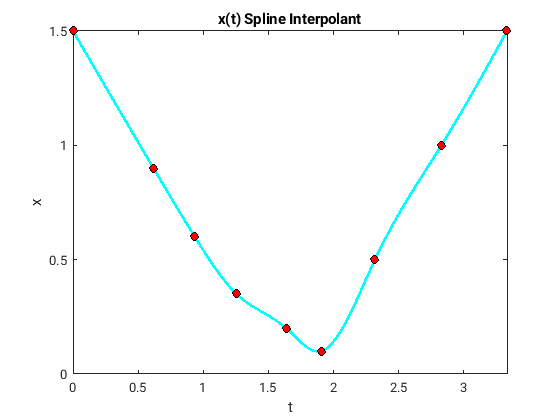

% plot curve
tp = linspace(t(1), t(end), 100);
xp = zeros(size(tp));
yp = zeros(size(tp));
for i = 1:length(tp)
    % find interval in which point tp(i) lies
    point = tp(i);
    interval = 1;
    for k = 1:np-1
        if point <= t(k+1)
            interval = k;
            break
        end
    end
    % x & y
    xp(i) = Ax(k)*(point - t(k))^3 + Bx(k)*(point - t(k))^2 + Cx(k)*(point - t(k)) + Dx(k);
    yp(i) = Ay(k)*(point - t(k))^3 + By(k)*(point - t(k))^2 + Cy(k)*(point - t(k)) + Dy(k);
end
figure()
plot(tp, xp, 'c-', 'LineWidth',2)
hold on
scatter(t, x, 'o', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black')
hold off
xlabel('t')
ylabel('x')
title('x(t) Spline Interpolant')
xlim([t(1) t(end)])

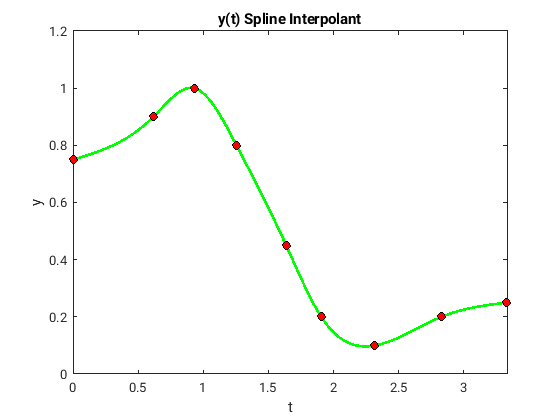

figure()
plot(tp, yp, 'g-', 'LineWidth',2)
hold on
scatter(t, y, 'o', 'MarkerFaceColor', 'red', 'MarkerEdgeColor','black')
hold off
xlabel('t')
ylabel('y')
title('y(t) Spline Interpolant')
xlim([t(1) t(end)])

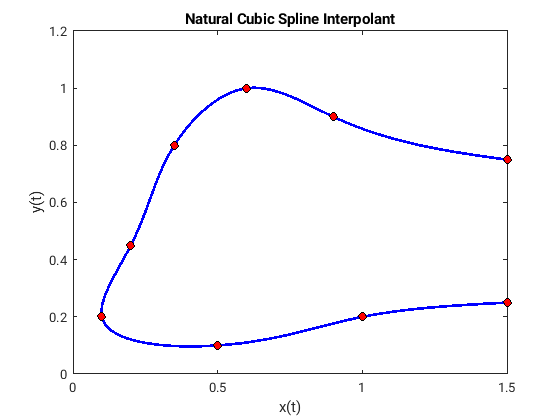

figure()
plot(xp, yp, 'b-', 'LineWidth',2)
hold on
scatter(x, y, 'o', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black')
hold off
xlabel('x(t)')
ylabel('y(t)')
title('Natural Cubic Spline Interpolant')

## `Function Definitions`

function [flag, x, LU] = GaussianElimination(A, b)
    % this function performs Gaussian elimination
    % and solves Ax = b
    % partial pivoting used
    
    % success flag (1 if successful, -1 if failed)
    flag = 0;
    % size of matrix
    n = size(A, 1);
    
    % initialise x
    x = zeros(n, 1);
    
    % make augmented matrix
    AugMatrix = [A b];
    
    for j = 1:n-1
        % find m (row index of largest value in each col)
        m = j;
        largest = abs(AugMatrix(m, j));
        for k = j:n
            if abs(AugMatrix(k, j)) > largest
                largest = abs(AugMatrix(k, j));
                m = k;
            end
        end
        
        % matrix is singular if abs(AugMatrix(m, j)) = 0
        % set flag to failed
        if largest == 0
            flag = -1;
            fprintf('Matrix is singular.')
            return
        end
        
        % exchange rows (row j and row m)
        for k = j:n+1
            tmp = AugMatrix(j, k);
            AugMatrix(j, k) = AugMatrix(m, k);
            AugMatrix(m, k) = tmp;
        end
        
        % compute multipliers
        for i =  j+1:n
            m = AugMatrix(i, j)/AugMatrix(j, j);
            for k = j+1:n+1
                AugMatrix(i, k) = AugMatrix(i, k) - m*AugMatrix(j, k);
            end
            % store multiplier
            AugMatrix(i, j) = m;
        end
    end
    
    % LU factorisation
    LU = AugMatrix(:, 1:n);
    
    % check for singularity
    prod = 1;
    for i = 1:n
        prod = prod*AugMatrix(i, i);
    end
    if prod == 0
        flag = -1;
        return
    end
    
    % back substitution
    for i = n:-1:1
        sum = 0;
        for k = i+1:n
            sum = sum + AugMatrix(i, k)*x(k);
        end
        x(i) = (AugMatrix(i, n+1) - sum)/AugMatrix(i, i);
    end
end


function x = tridiagsolver(A, d)
    % tridiagonal solver (A is tri-diagonal)
    
    % size of matrix
    n = size(A, 1);
    
    % upper diagonal of A = b(i) = A(i, i+1)
    % lower diagonal of A = c(i) = A(i+1, i)
    % diagonal of A = a(i) = A(i, i)
    
    % compute LU decomposition of A
    m = zeros(n, 1);
    l = zeros(n-1, 1);
    m(1) = A(1, 1);
    for j = 1:n-1
        l(j) = A(j+1, j)/m(j);
        m(j+1) = A(j+1, j+1) - l(j)*A(j, j+1);
    end
    
    % forward substitution on Ly = d
    y = zeros(n, 1);
    y(1) = d(1);
    for j = 2:n
        y(j) = d(j) - l(j-1)*y(j-1);
    end
    
    % backward substitution on Ux = y
    x = zeros(n, 1);
    x(n) = y(n)/m(n);
    for j = n-1:-1:1
        x(j) = (y(j) - A(j, j+1)*x(j+1))/m(j);
    end
end